# Run 2nd

% RegionID = 'QLD1';
% timespan = datetime(2011,1,1):calmonths(1):datetime(2022,12,1);
% PHSdata = funcPHSdata(timespan, RegionID, 'wivenhoe');

Pdata = PHSdata(PHSdata.PHSpump>0,:);
Gdata = PHSdata(PHSdata.PHSgen>0,:);

str = num2str(start_date);y1 = str2double(str(1:4));
str = num2str(end_date);y2 = str2double(str(1:4));


yearly = y1:y2;
cost=[];reve=[];
wavPumpRRP=[];wavGenRRP=[];
MWhPump=[];MWhGen=[];
for ii = 1:length(yearly)
    k = Pdata(year(Pdata.SETTLEMENTDATE)==yearly(ii),:);
    cost(ii) = sum(k.PHSpump.*k.RRP)*5/60;
    MWhPump(ii) = sum(k.PHSpump)*5/60;
    wavPumpRRP(ii) = cost(ii)/MWhPump(ii);
        
    k = Gdata(year(Gdata.SETTLEMENTDATE)==yearly(ii),:);
    reve(ii) = sum(k.PHSgen.*k.RRP)*5/60;
    MWhGen(ii) = sum(k.PHSgen)*5/60;
    wavGenRRP(ii) = reve(ii)/MWhGen(ii);     
end

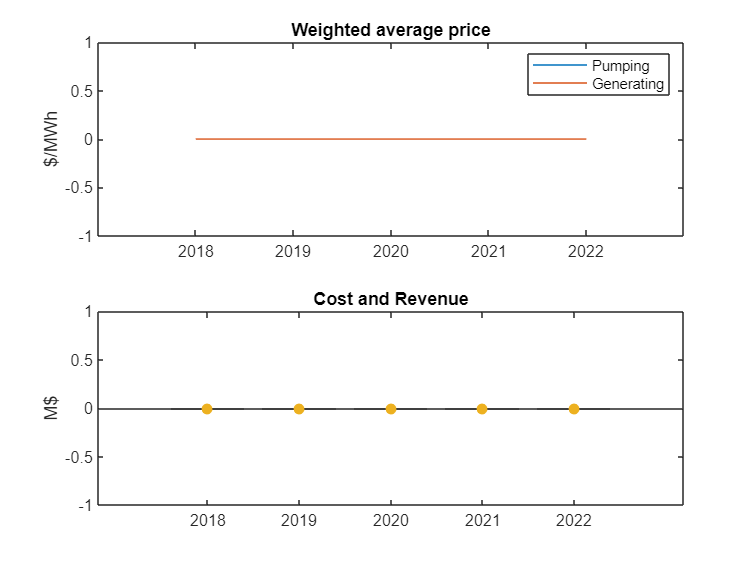

clf;
subplot(2,1,1);
    plot(yearly,wavPumpRRP,yearly,wavGenRRP);ylabel('$/MWh');
    title('Weighted average price')
    legend('Pumping','Generating')
    xlim([y1-1 y2+1])
    xticks(y1:y2)
subplot(2,1,2);
    bar(yearly,-cost*1e-6);
    hold on
    bar(yearly,reve*1e-6)
    scatter(yearly,1e-6*(reve-cost),'filled')
    title('Cost and Revenue');ylabel('M$')

% clf
% timegroup = year(Gdata.SETTLEMENTDATE);
% boxplot(Gdata.RRP,timegroup)
% title('Price in Generating mode')
% ylabel('$/MWh')
% ylim([-200 600])
% xlim([2.50 7.50])

% clf
% timegroup = year(Pdata.SETTLEMENTDATE);
% boxplot(Pdata.RRP,timegroup)
% title('Price in Pumping mode')
% ylabel('$/MWh')
% ylim([-200 600])
% xlim([2.50 7.50])

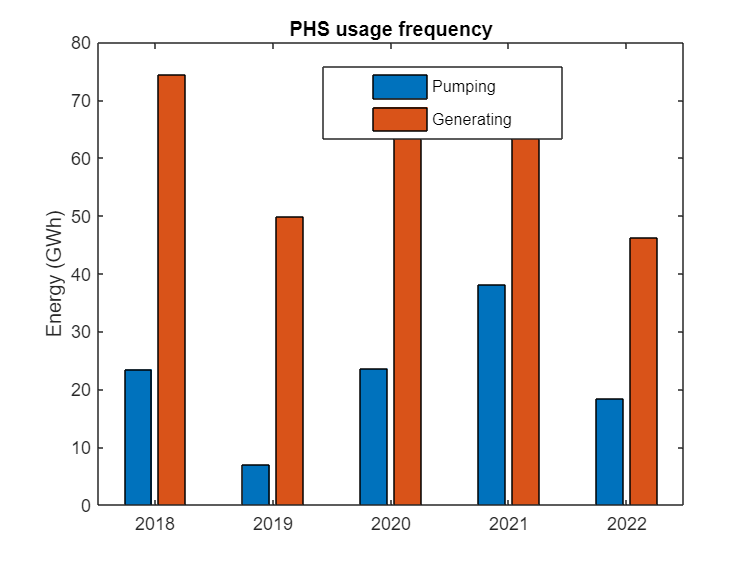

clf
bar(yearly,[MWhPump;MWhGen]*1e-3,'grouped')
legend('Pumping','Generating')
ylabel('Energy (GWh)')
title('PHS usage frequency')

legend('Position',[0.42838,0.75542,0.31579,0.12695])